# Op-Amp Circuit - Differentiator

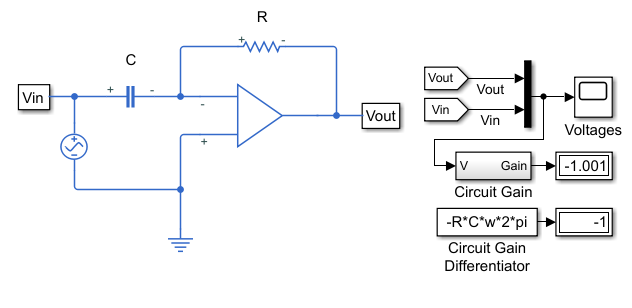

This model shows a differentiator, such as might be used as part of a PID controller. It also illustrates how numerical simulation issues can arise in some idealized circuits. The model runs with the capacitor series parasitic resistance set to its default value of 1e-6 Ohms. Setting it to zero results in a warning and a very slow simulation. See the User's Guide for further information.

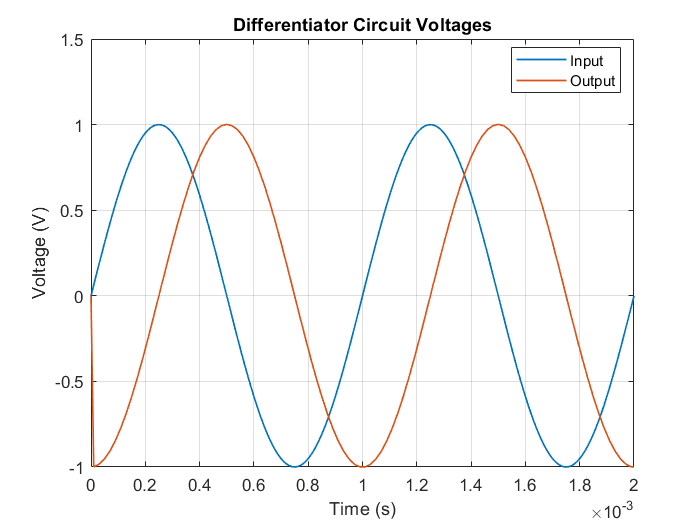

% Code to plot simulation results from ssc_opamp_differentiator

% Copyright 2015 The MathWorks, Inc.

% Reuse figure if it exists, else create new figure
try
    figure(h1_ssc_opamp_differentiator)
catch
    h1_ssc_opamp_differentiator=figure('Name', 'ssc_opamp_differentiator');
end

% Generate simulation results if they don't exist
if(~exist('simlog_ssc_opamp_differentiator','var'))
    sim('ssc_opamp_differentiator')
end

% Get simulation results
temp_vin = simlog_ssc_opamp_differentiator.AC_Voltage.v.series;
temp_vout = simlog_ssc_opamp_differentiator.Op_Amp.out.v.series;

% Plot results
plot(temp_vin.time,temp_vin.values,'LineWidth',1);
hold on
plot(temp_vout.time,temp_vout.values,'LineWidth',1);
hold off
grid on
title('Differentiator Circuit Voltages');
ylabel('Voltage (V)');
xlabel('Time (s)');
legend({'Input','Output'},'Location','Best');


% Remove temporary variables
clear temp_vin temp_vout